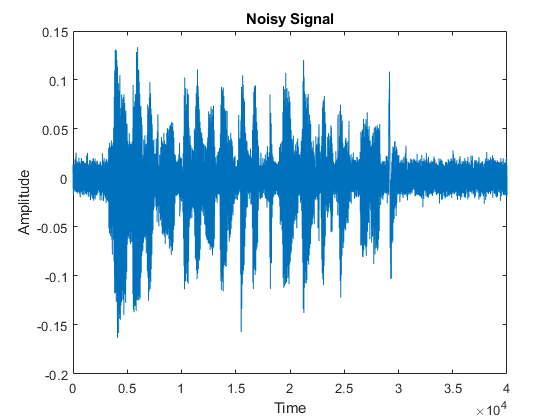

% Load the clean audio file
[cleanSignal, Fs] = audioread('MusaZaheer_BSCE21037.wav');

% Generate and add white Gaussian noise to the audio signal
SNR_dB = 10; % Signal-to-Noise Ratio in dB
SNR = 10^(SNR_dB/10); % Convert SNR from dB to linear scale
noisePower = var(cleanSignal) / SNR;
noiseSignal = sqrt(noisePower) * randn(size(cleanSignal));
noisySignal = cleanSignal + noiseSignal;

% Remove the added noise using a filter
filterCoefficients = fir1(32, 0.5); % Example of FIR filter design
filteredSignal = filter(filterCoefficients, 1, noisySignal);

% Evaluate the performance criteria of the filter
SNR_clean = snr(cleanSignal);
SNR_filtered = snr(filteredSignal);

% Save the noisy and filtered signals as .wav files
audiowrite('noisy_signal.wav', noisySignal, Fs);
audiowrite('filtered_signal.wav', filteredSignal, Fs);
sound(filteredSignal, Fs);
%sound(noisySignal, Fs);
% Plot the signals
plot(noisySignal);
title('Noisy Signal');
xlabel('Time');
ylabel('Amplitude');

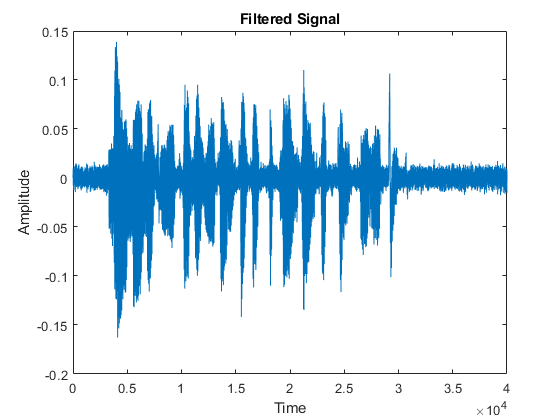


figure;
plot(filteredSignal);
title('Filtered Signal');
xlabel('Time');
ylabel('Amplitude');